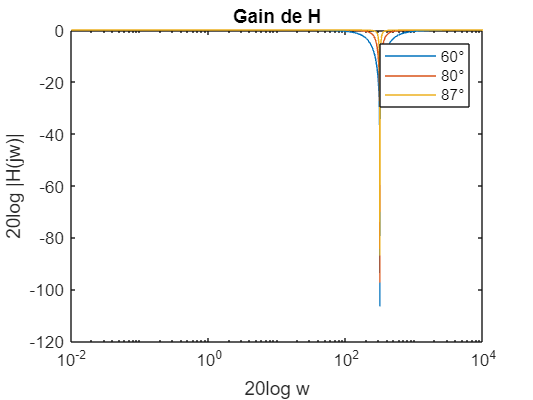

f_0 = 50;
w_0 = 2*pi*f_0;
theta = [60*pi/180 80*pi/180 87*pi/180];
theta = transpose(theta);

w = 0 : 0.01 : 10000;
S = 1i*w;
H = (S.^2 + w_0^2) ./ (S.^2 + 2*w_0*cos(theta)*S + w_0.^2);
module = 20*log10(abs(H));
phase = angle(H);

figure('name', 'Gain de H');
semilogx(w, module);
title('Gain de H');
xlabel('20log w');
ylabel('20log |H(jw)|');
legend('60°', '80°', '87°');

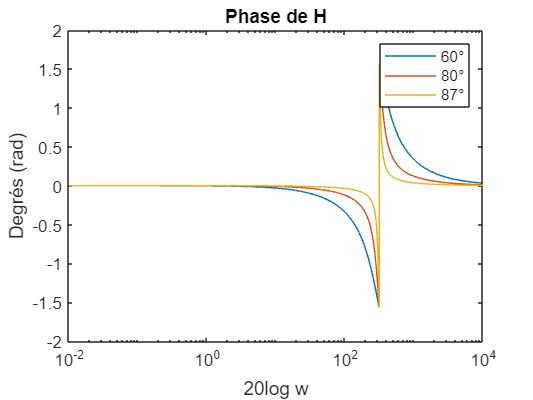


figure('name', 'Phase de H');
semilogx(w, phase);
title('Phase de H');
xlabel('20log w');
ylabel('Degrés (rad)');
legend('H');
legend('60°', '80°', '87°');